%%
clf;
% rng('default');
rng(5);
rng

ans = 包含以下字段的 struct :
     Type: 'twister'
     Seed: 5
    State: [625×1 uint32]


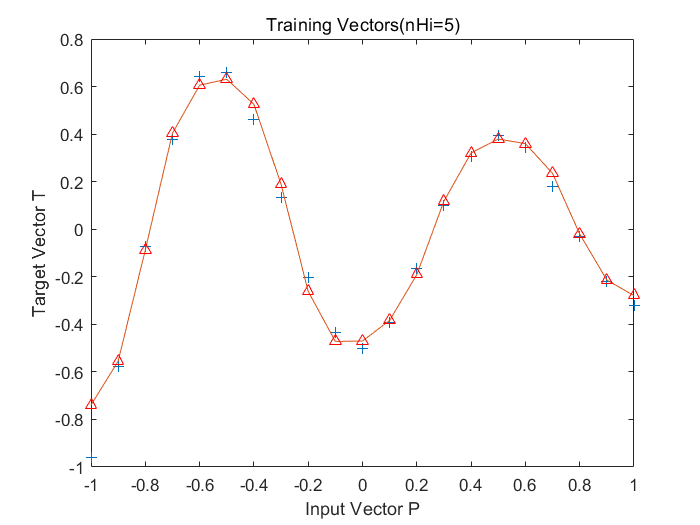

flag=0;   % 1=单步执行；0=连续执行
%设定目标函数值
P = -1:.1:1;
T = [-.9602 -.5770 -.0729  .3771  .6405  .6600  .4609 ...
      .1336 -.2013 -.4344 -.5000 -.3930 -.1647  .0988 ...
      .3072  .3960  .3449  .1816 -.0312 -.2189 -.3201];
%设置训练超参数
maxiter = 2000;         %最大迭代次数
eta = 0.6;              %学习率
mc = 0.8;               %动量因子
eb = 0.001;              %误差容限度

%建立网络
nHi = 5;                % 隐藏层数目为5
net=feedforwardnet(nHi);
net.trainFcn ='trainbfg';
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
%训练网络
[net,tr] = train(net, P, T);
train_out = sim(net, P);
% errRec = tr.perf;

figure(1);
plot(P,T,'+');
hold on;
plot(P,train_out);
plot(P,train_out,'r^');
title('Training Vectors(nHi=5)');
xlabel('Input Vector P');
ylabel('Target Vector T');

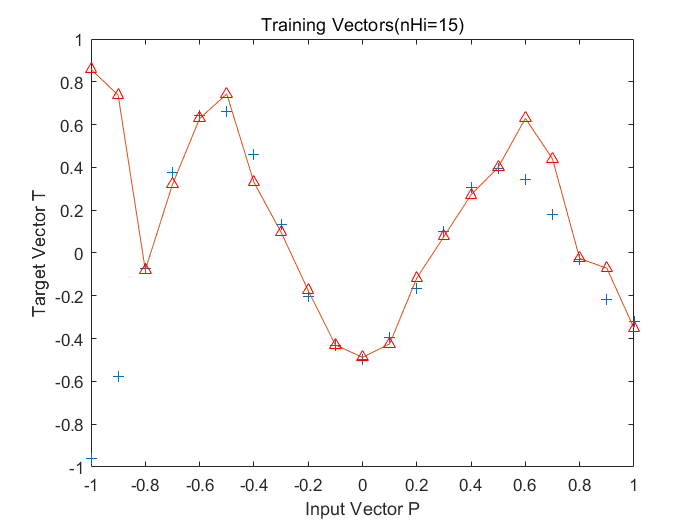


nHi = 15;               % 隐藏层数目为15
net=feedforwardnet(nHi);
net.trainFcn ='trainbfg';
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
[net,tr] = train(net, P, T);
train_out = sim(net, P);

figure(2);
plot(P,T,'+');
hold on;
plot(P,train_out);
plot(P,train_out,'r^');
title('Training Vectors(nHi=15)');
xlabel('Input Vector P');
ylabel('Target Vector T');


%隐藏层更多的时候，BP网络更容易过拟合。

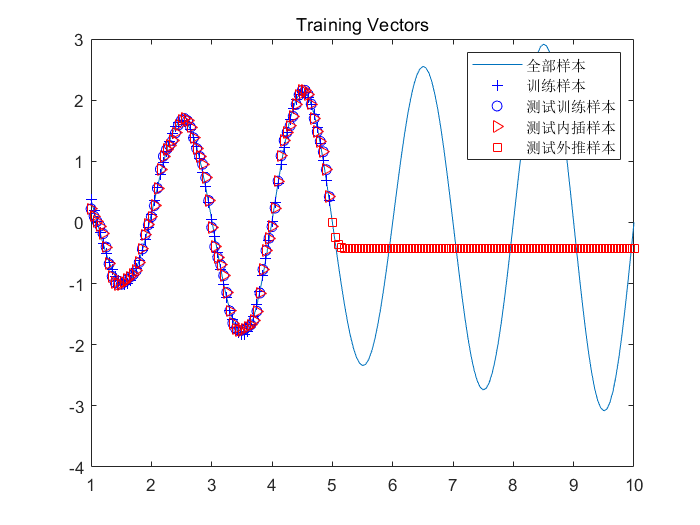

clf;
rng(5);
rng;

P = 1:.05:10;
T = exp(-P)+(P.^0.5).*sin(pi*P);
train_d = P(1:80);              %训练用数据
train_l = T(1:80);              %训练用label
trian_iner = P(1:80);           %内插训练数据
test_extra = P(81:181);         %外推测试数据
%设置训练超参数
maxiter = 2000;         %最大迭代次数
eta = 0.6;              %学习率
mc = 0.8;               %动量因子
eb = 0.001;              %误差容限度
nHi = 15;                % 隐藏层数目
%建立网络
net.trainParam.epochs = maxiter;
net.trainParam.goal = eb;
net.trainParam.lr = eta;
net.trainParam.mc = mc;
net=feedforwardnet(nHi);
net.trainFcn = 'trainbfg';
%训练网络
[net,tr] = train(net, train_d, train_l);
train_out = sim(net, train_d);
trian_inter_out = sim(net, trian_iner);
test_extra_out = sim(net, test_extra);

plot(P,T);
hold on;
plot(train_d, train_l,'+','MarkerEdgeColor','b');
plot(train_d,train_out,'o', 'MarkerEdgeColor','b');
plot(trian_iner, trian_inter_out,'>','MarkerEdgeColor','r');
plot(test_extra, test_extra_out,'s','MarkerEdgeColor','r');
legend('全部样本', '训练样本', '测试训练样本', '测试内插样本', '测试外推样本');
title('Training Vectors');